# Monte Carlo of GoHorse Optimization - *fminsearch(.)*

Default config

close all;
clear;
clc;
set(0,'defaultfigurecolor',[1 1 1]);

Initialize variables and set the Monte Carlo configurations

MCruns = 100;

par = cell(MCruns,1);
J = cell(MCruns,1);
e_flag = cell(MCruns,1);
cruze_par = cell(MCruns,1);

## Generate the data or load pre-saved ones

Define the number of information data

ppH = 2;
resolution = 10000;
space = 'random';
noise = 'white';
SNR = 40; %dB

W = autoGen(14);

ind = cell(length(W(:,1)),1);
for i = 1 : length(W(:,1))
if strcmp(space,'random')
    ppW = round(W(i,2)*ppH,0);
    cruze = 2*rand(ppW,1)./ppH - 1/ppH;
    i_cruze = round(cruze*resolution/W(i,2),0);
    
    ind{i} = unique(sort(abs(round(linspace(1,resolution,ppW),0) + i_cruze')));
elseif strcmp(space,'linear')
    ind{i} = unique(round(linspace(1,resolution,ppW),0)); 
end

if ind{i}(end) > resolution; ind{i}(end) = resolution; end
if ind{i}(1) <= 0; ind{i}(1) = 1; end
end

## Optimization setup

options = optimset('Display','off','MaxIter',100,'UseParallel',true);
prop = .4;

## Real parameters

rPar(1) = pi/12; %omega
rPar(2) = 1/0.0353; %tau
rPar(3) = 2.52; %M
rPar(4) = -16.835*pi/12; %cPhase
rPar(5) = 2.4; %offset
rPar(6) = 14.3; %y_oo
rPar(7) = 2.6247; %tau_e

TexNames{1} = '$$\omega_n$$'; 
TexNames{2} = '$$\tau$$';
TexNames{3} = '$$M$$'; 
TexNames{4} = '$$\phi_{c}$$'; 
TexNames{5} = '$$A_{DC}$$'; 
TexNames{6} = '$$y_{\infty}$$';
TexNames{7} = '$$\tau_{e}$$';

## Initialize the Monte Carlo Simulations

for mc = 1 : MCruns
    
    [dtd,dta] = alertness_sim(W,noise,SNR,resolution,ind);
    
    est_d = 7;
    
    dte.y = dtd.y(1:est_d); dte.t = dtd.t(1:est_d);
    dte.init = dtd.initial(1:est_d); dte.final = dtd.final(1:est_d); 
    dte.valid.y = dtd.y(est_d+1:end); dte.valid.t = dtd.t(est_d+1:end);
    dte.valid.init = dtd.initial(est_d+1:end); dte.valid.final = dtd.final(est_d+1:end);
    
    cruze_par{mc} = prop.*rPar.*(rand(1,length(rPar))-.5);
    
    init = rPar + cruze_par{mc};
    
    [par{mc},J{mc},e_flag{mc}] = fminsearch(@ghCost,init,options,dte);
    
    disp(['Monte Carlo run ',num2str(mc),...
                             ' Quadratic Error: ',num2str(J{mc})]);
end

Monte Carlo run 1 Quadratic Error: 1.4405
Monte Carlo run 2 Quadratic Error: 0.0034709
Monte Carlo run 3 Quadratic Error: 1.414
Monte Carlo run 4 Quadratic Error: 1.483
Monte Carlo run 5 Quadratic Error: 0.0028949
Monte Carlo run 6 Quadratic Error: 1.1808
Monte Carlo run 7 Quadratic Error: 1.5001
Monte Carlo run 8 Quadratic Error: 0.005339
Monte Carlo run 9 Quadratic Error: 1.3272
Monte Carlo run 10 Quadratic Error: 1.4297
Monte Carlo run 11 Quadratic Error: 1.4333
Monte Carlo run 12 Quadratic Error: 1.5166
Monte Carlo run 13 Quadratic Error: 0.010032
Monte Carlo run 14 Quadratic Error: 1.4799
Monte Carlo run 15 Quadratic Error: 1.4177
Monte Carlo run 16 Quadratic Error: 0.0069313
Monte Carlo run 17 Quadratic Error: 0.0087711
Monte Carlo run 18 Quadratic Error: 0.00062272
Monte Carlo run 19 Quadratic Error: 0.0041006
Monte Carlo run 20 Quadratic Error: 1.4688
Monte Carlo run 21 Quadratic Error: 0.0022395
Monte Carlo run 22 Quadratic Error: 1.6402
Monte Carlo run 23 Quadratic Error: 0.0

## Monte Carlo figures

Plot the optimization output flags propotions and the cost function results 

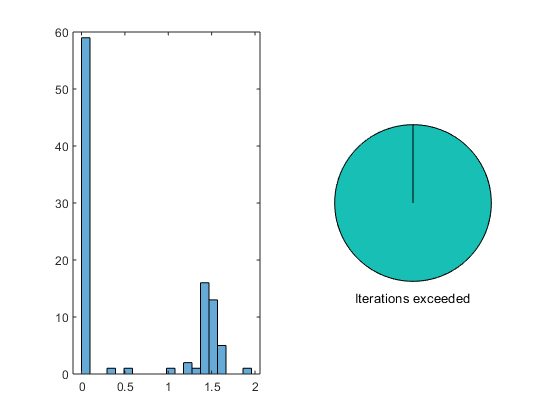

figure(2); hold on;
subplot(1,2,1);
histogram(cell2mat(J),20);
subplot(1,2,2);
labels = {'Function Terminated','Iterations exceeded','Converged to solution'};
flags = cell2mat(e_flag)'+2;
e_flags = [count(num2str(flags),"1"), count(num2str(flags),"2"), count(num2str(flags),"3")];
pie(e_flags,labels);

Generate the visualization from for the cruze signal variations

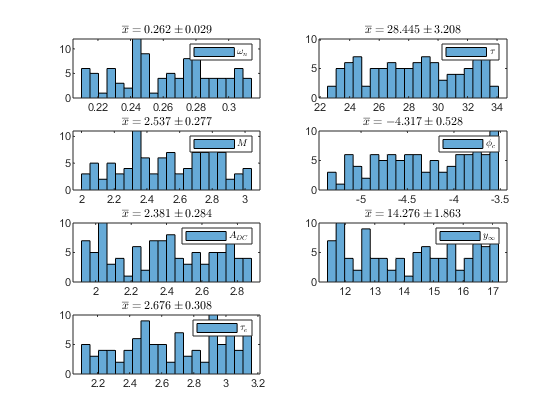

figure(3); hold on;
title('Parameters initialization cruzing','Interpreter','latex');
aux = cell2mat(cruze_par);
for i = 1 : 7
   subplot(4,2,i); 
   histogram(aux(:,i)+rPar(i),20); hold on;
   title(['$$\overline{x} =',num2str(round(mean(aux(:,i)+rPar(i)),3)),...
       '\pm',num2str(round(std(aux(:,i)+rPar(i)),3)),'$$'],...
       'Interpreter','latex');
   leg = TexNames{i};
   legend(leg,'Interpreter','latex');
end

Plot the proportional error for each parameter at each run

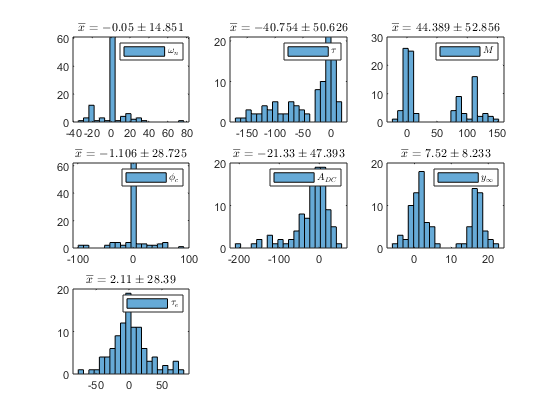

figure(4); hold on;
title('Parameters error on finalization','Interpreter','latex');
aux_i = cell2mat(par);
for i = 1 : 7
   subplot(3,3,i);
   e_prop = 100.*(rPar(i) - aux_i(:,i))/rPar(i); 
   histogram(e_prop,20);
   title(['$$\overline{x} =',num2str(round(mean(e_prop),3)),...
       '\pm',num2str(round(std(e_prop),3)),'$$'],'Interpreter','latex');
   leg = TexNames{i};
   legend(leg,'Interpreter','latex'); 
end